# Analisis del PID

**Identificacion de la planta por respuesta al escalon y sintonia del PID**

La cadena seria 

**medir **-> **filtrar **-> **identificar un modelo **-> **disenar el PID sobre el modelo **-> **llevarlo a un microcontrolador **

clear; clc; close all;
rng(1);

## 1. La cadena completa

- **El modelo fisico**: la maqueta ball and beam (servo, viga, bola, sensor).

- **Experimento**: se aplica un escalon y se registra la respuesta.

- **Medicion**: la senal medida trae ruido de sensor y cuantizacion.

- **Filtrado**: se limpia el ruido lo justo, sin deformar la respuesta.

- **Extraccion de rasgos**: valor final, sobrepico y tiempo de pico.

- **Modelo**: con esos rasgos se calcula la funcion de transferencia G(s).

- **Validacion**: se compara la respuesta del modelo con la medida.

- **Diseno del PID**: se prueban Kp, Ti y Td sobre el modelo, en simulacion.

- **Discretizacion**: se pasa el controlador a tiempo discreto (Ts = 20 ms).

- **Implementacion y ajuste fino**: se carga en el STM32 y se corrige.

**Idea central:** los pasos 1 a 7 sirven para **conocer el modelo analiticamente**. Recien en los pasos 8 a 10 se trabaja con el **controlador**. 

## 2. Fundamentos del lazo PID

El controlador PID calcula la senal de control a partir del error $e(t) = r(t) - y(t)$, con $r$ la referencia e $y$ la medicion.

En la forma estandar (lo que esta en la consigna):


$$u(t) = K_p \left[ e(t) + \frac{1}{T_i}\int_0^t e(\tau)\,d\tau + T_d \frac{de(t)}{dt} \right]$$


Las equivalencias con la forma algoritmica son $K_i = K_p/T_i$ y $K_d = K_p T_d$. En Laplace:


$$C(s) = K_p \left( 1 + \frac{1}{T_i s} + T_d s \right)$$


Con una planta $G(s)$ y realimentacion unitaria, el lazo cerrado es


$$T(s) = \frac{C(s)\,G(s)}{1 + C(s)\,G(s)}$$


Los **polos** de $T(s)$ (las raices del denominador) determinan si el sistema es estable y como responde. Por eso conocer $G(s)$ es lo que queremos hacer: permite calcular donde caen los polos para cada eleccion de Kp, Ti y Td, sin tocar la maqueta.

**Efecto de cada accion:**

- **P**: reacciona al error actual. Mas Kp, respuesta mas rapida pero mas oscilante.

- **I**: acumula el error pasado. Elimina el error estacionario frente a perturbaciones constantes. Un Ti chico es mas agresivo.

- **D**: reacciona a la velocidad del error. Actua como freno y suma amortiguamiento. Amplifica el ruido.

## 3. El sistema de segundo orden

Muchos sistemas, o al menos su comportamiento dominante, se parecen a un segundo orden:


$$G(s) = \frac{K\,\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$


con tres parametros:

- $K$: ganancia estatica (hacia donde se asienta la salida por unidad de entrada).

- $\zeta$: amortiguamiento (cuanto oscila).

- $\omega_n$: frecuencia natural (que tan rapido es).

Los polos son $s = -\zeta\omega_n \pm j\omega_n\sqrt{1-\zeta^2}$. Para $0<\zeta<1$ son complejos conjugados y la respuesta al escalon es oscilatoria amortiguada. 

Definimos la frecuencia amortiguada $\omega_d = \omega_n\sqrt{1-\zeta^2}$.

La respuesta al escalon unitario tiene tres rasgos medibles:


$$y_{ss} = K \qquad T_p = \frac{\pi}{\omega_d} \qquad OS = e^{-\zeta\pi/\sqrt{1-\zeta^2}}$$


donde $y_{ss}$ es el valor final, $T_p$ el tiempo de pico y $OS$ el sobrepico (como fraccion, por ejemplo 0.2 = 20 %). Ademas, el tiempo de asentamiento (2 %) es aproximadamente $T_s \approx 4/(\zeta\omega_n)$.

Aca va un ejemplo de cómo cambia la forma de la respuesta con $\zeta$, dejando fijos $K = 1$ y $\omega_n = 6$ rad/s:

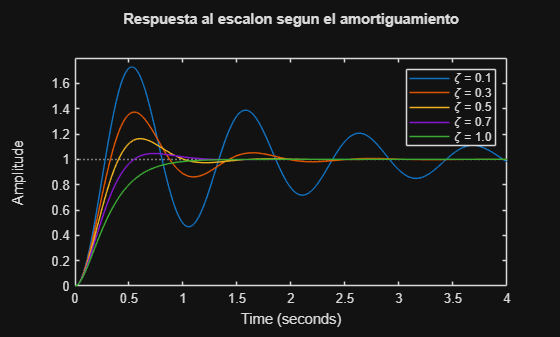

wn = 6;
zetas = [0.1 0.3 0.5 0.7 1.0];
t = (0:0.002:4)';

figure; hold on; grid on;
for z = zetas
    step(tf(wn^2, [1, 2*z*wn, wn^2]), t);
end
leyenda = arrayfun(@(z) sprintf('\\zeta = %.1f', z), zetas, 'UniformOutput', false);

legend(leyenda);
title('Respuesta al escalon segun el amortiguamiento');

% Sobrepico teorico para cada zeta:

    zeta    OS_porcentaje
    ____    _____________

    0.1        72.925    
    0.3        37.233    
    0.5        16.303    
    0.7        4.5988    
      1             0    



OS_teorico = 100*exp(-pi*zetas./sqrt(1-zetas.^2));
disp(table(zetas', OS_teorico', 'VariableNames', {'zeta','OS_porcentaje'}));

% Observacion: cuanto mayor es zeta, menor es el sobrepico. Con zeta = 1 ya
% no hay sobrepico: el metodo de la seccion 4 no se puede aplicar ahi.

## 4. El metodo, paso a paso

**Que hace el metodo:** desde la curva medida lee tres numeros y los traduce a los tres parametros del modelo.

**Paso 1. Ganancia.** La salida se asienta en $y_{ss}$. Si el escalon de entrada tuvo amplitud $A$:


$$K = \frac{y_{ss}}{A}$$


**Paso 2. Sobrepico y tiempo de pico.** Se busca el maximo de la curva:


$$OS = \frac{y_{max} - y_{ss}}{y_{ss}}, \qquad T_p = t(y_{max})$$


**Paso 3. Amortiguamiento.** Se despeja $\zeta$ de la formula del sobrepico. Tomando logaritmo, $\ln(OS) = -\zeta\pi/\sqrt{1-\zeta^2}$. Elevando al cuadrado y despejando:


$$\zeta = \frac{-\ln(OS)}{\sqrt{\pi^2 + \ln^2(OS)}}$$


**Paso 4. Frecuencia natural.** De $T_p = \pi/\omega_d$:


$$\omega_d = \frac{\pi}{T_p}, \qquad \omega_n = \frac{\omega_d}{\sqrt{1-\zeta^2}}$$


**Paso 5. Modelo.** Se arma $G(s)$ con K, zeta y wn.

Lo probamos sobre un sistema "verdadero" que el metodo no conoce:

K_real = 2;  zeta_real = 0.35;  wn_real = 6;
G_real = tf(K_real*wn_real^2, [1, 2*zeta_real*wn_real, wn_real^2]);

A = 1;                                   % amplitud del escalon aplicado
t = (0:0.005:5)';
y = A*step(G_real, t);                   % "medicion" (en la maqueta: el log)

% Paso 1: ganancia (promedio del ultimo 10 % para el valor final)
n10 = round(0.10*numel(y));
yss = mean(y(end-n10:end));
K   = yss/A;

% Paso 2: pico
[ymax, idx] = max(y);
Tp = t(idx);
OS = (ymax - yss)/yss;

% Paso 3 y 4: parametros
zeta = -log(OS)/sqrt(pi^2 + log(OS)^2);
wd   = pi/Tp;
wn   = wd/sqrt(1 - zeta^2);

% Paso 5: modelo
G_id = tf(K*wn^2, [1, 2*zeta*wn, wn^2]);

fprintf('          real    estimado\n');

          real    estimado


fprintf('K      : %6.3f   %6.3f\n', K_real,    K);

K      :  2.000    2.000


fprintf('zeta   : %6.3f   %6.3f\n', zeta_real, zeta);

zeta   :  0.350    0.350


fprintf('wn     : %6.3f   %6.3f\n', wn_real,   wn);

wn     :  6.000    5.989


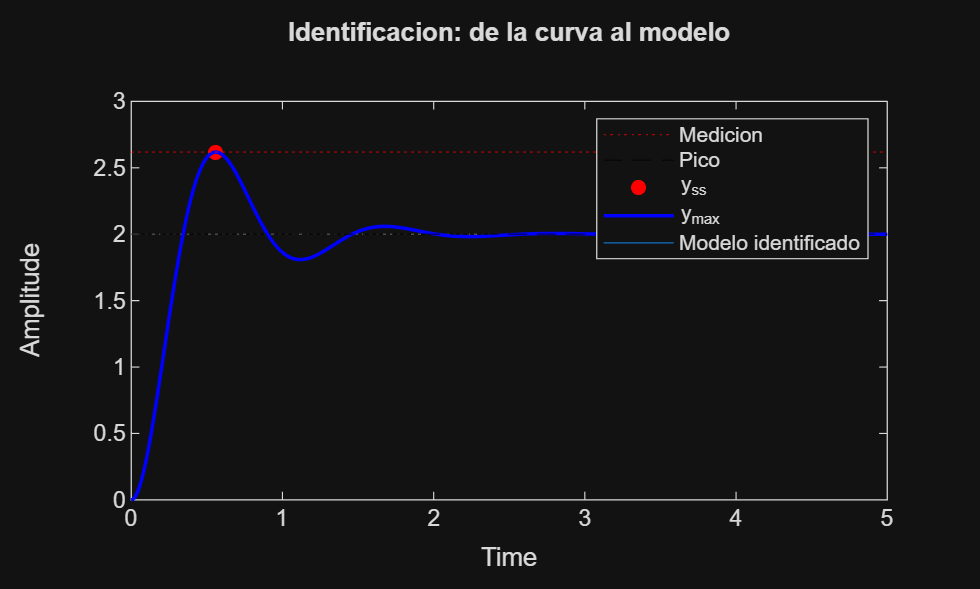


figure; hold on; grid on;
plot(t, y, 'b', 'LineWidth', 1.5);
plot(Tp, ymax, 'ro', 'MarkerFaceColor', 'r');
yline(yss, '--k');
yline(ymax, ':r');
step(A*G_id, t);
legend('Medicion', 'Pico', 'y_{ss}', 'y_{max}', 'Modelo identificado');
title('Identificacion: de la curva al modelo');

aca se va a ver igual , van a quedar superpuestos, pq es una planta de segundo orden exacta, puesto que no tiene ruido, entonces va a coincidir el modelo con la medicion practicamente en todos los puntos. En el sistema real tenemos ruido.

## 5. Ruido y filtrado

Un sensor real agrega ruido. Como el metodo depende de **un solo punto** (el maximo), el ruido lo afecta mucho: un pico espurio cambia el sobrepico y el tiempo de pico.

Una solucion simple es una media movil de ventana $N$:


$$\bar{y}_k = \frac{1}{N}\sum_{j} y_{k+j}$$


**Trade off:** una ventana chica deja pasar ruido; una ventana grande lo elimina pero tambien aplasta el pico y subestima el sobrepico. Hay que elegir una ventana mucho menor que el periodo de la oscilacion.

Probamos varias ventanas sobre la misma medicion ruidosa:

sigma = 0.02;                            % desvio del ruido
yr = y + sigma*randn(size(y));

ventanas = [1 5 15 41 101];
fprintf('Real: K=%.3f zeta=%.3f wn=%.3f\n', K_real, zeta_real, wn_real);

Real: K=2.000 zeta=0.350 wn=6.000


fprintf('ventana     K      zeta     wn\n');

ventana     K      zeta     wn


for k = 1:numel(ventanas)
    [~, ik] = identificarEscalon(t, yr, A, ventanas(k));
    fprintf('%6d   %6.3f  %6.3f  %6.3f\n', ventanas(k), ik.K, ik.zeta, ik.wn);
end

     1    2.006   0.338   6.419
     5    2.006   0.348   5.879
    15    2.006   0.353   6.105
    41    2.006   0.367   5.977
   101    2.007   0.448   5.714


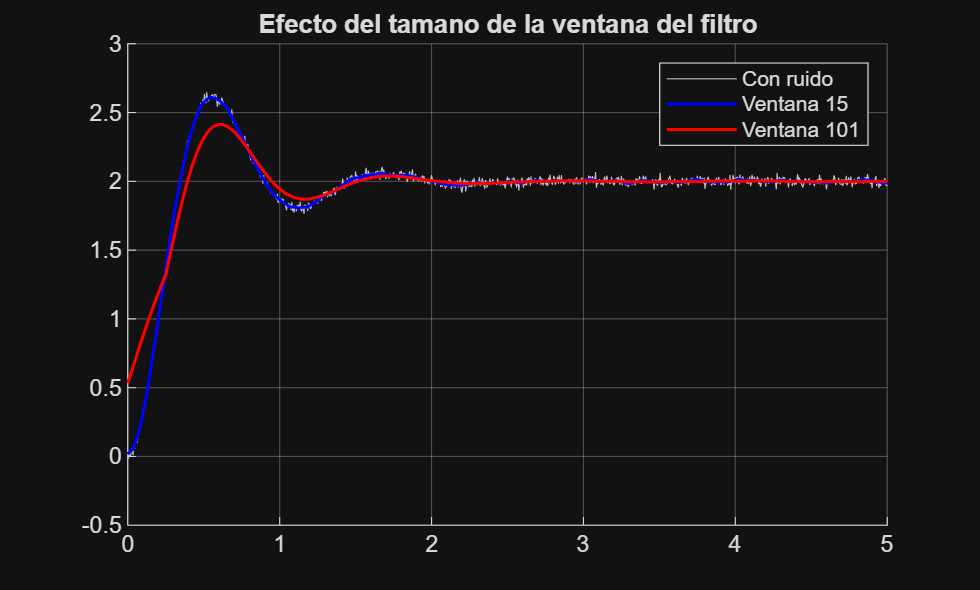


figure; hold on; grid on;
plot(t, yr, 'Color', [0.75 0.75 0.75]);
plot(t, movmean(yr, 15), 'b', 'LineWidth', 1.3);
plot(t, movmean(yr, 101), 'r', 'LineWidth', 1.3);
legend('Con ruido', 'Ventana 15', 'Ventana 101');
title('Efecto del tamano de la ventana del filtro');


% Con 101 muestras (0.5 s) el pico queda aplastado: ejemplo de sobrefiltrado.

## 6. Limitaciones del metodo

El metodo supone dos cosas, sin eso dejaria de ser válido:

- **El sistema es de segundo orden subamortiguado.**

- **El sobrepico es medible** (no tapado por el ruido).

**Caso A: amortiguamiento alto.** Con $\zeta$ cercano a 1 el sobrepico es minusculo y cualquier ruido lo tapa. Para $\zeta \ge 1$ directamente no hay sobrepico.

**Caso B: planta de orden mayor.** Un polo extra (por ejemplo, la dinamica de un servo) hace que la planta no sea de segundo orden. El metodo igual entrega un modelo, pero aproximado:

G3 = G_real * tf(1, [0.08 1]);           % polo extra en 12.5 rad/s
y3 = A*step(G3, t);
[G3_id, i3] = identificarEscalon(t, y3, A);
fprintf('Planta 3er orden -> K=%.3f zeta=%.3f wn=%.3f (real 2do: %.2f / %.2f / %.2f)\n', ...
        i3.K, i3.zeta, i3.wn, K_real, zeta_real, wn_real);

Planta 3er orden -> K=2.000 zeta=0.383 wn=5.273 (real 2do: 2.00 / 0.35 / 6.00)


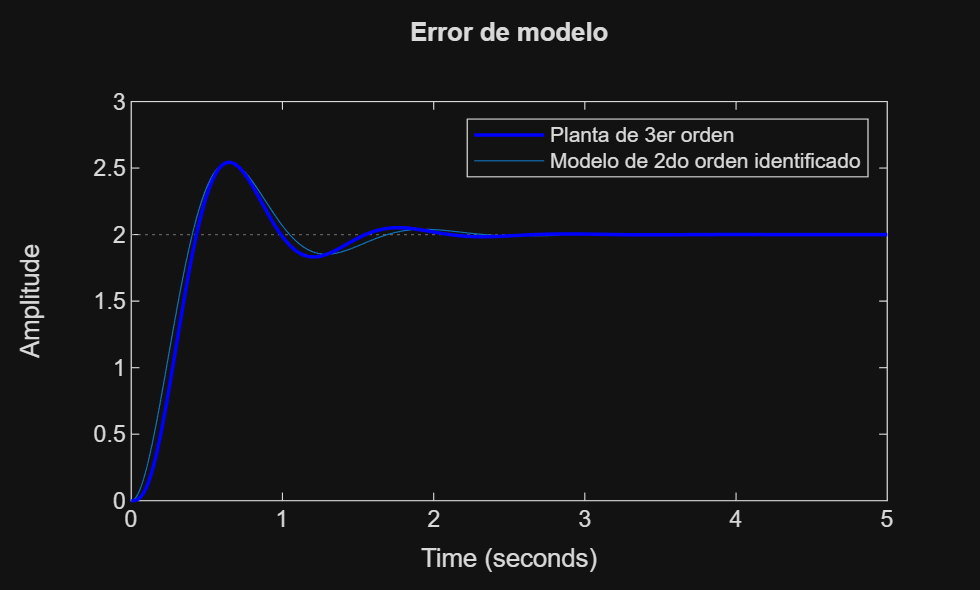


figure; hold on; grid on;
plot(t, y3, 'b', 'LineWidth', 1.5);
step(A*G3_id, t);
legend('Planta de 3er orden', 'Modelo de 2do orden identificado');
title('Error de modelo');

Para saber si el modelo sirve, tendria que superponer la rta del modelo y la medida, si maome coinciden va todo, sino hay que cambiar el modelo.

## 7. El Ball and Beam: modelo fisico

La bola rueda sobre la viga inclinada un angulo $\theta$. Para una bola solida que rueda sin deslizar (con masa $m$, radio $r$), la energia se reparte entre traslacion y rotacion, y queda


$$\left(1 + \frac{2}{5}\right)\ddot{x} = g\sin\theta \;\;\Rightarrow\;\; \ddot{x} \approx \frac{5}{7}\,g\,\theta$$


para angulos chicos. O sea que **la aceleracion de la bola es proporcional al angulo. **En Laplace:


$$G_{bb}(s) = \frac{X(s)}{\Theta(s)} = \frac{K_b}{s^2}, \qquad K_b = \frac{5g}{7} \approx 7\ \mathrm{m/s^2/rad}$$


Que es Kb: es la ganancia de la planta. Dice cuanta aceleracion recibe la bola por cada radian de inclinacion de la viga: 

                                                                                                                                                                                  
$$\frac{d^2 x}{dt^2} = K_b \theta$$


Por ejemplo, con Kb = 7 y una viga inclinada 0.05 rad, la bola acelera a 0.35 metros por segundo cuadrado. Es el unico numero que le falta al modelo para quedar completo.

*Por que hay que medirlo: la formula 5g/7 es el valor teorico. En la maqueta real el valor cambia segun el tipo de bola (hueca o maciza), el rozamiento, como el angulo del servo se traduce en angulo de la viga y la calibracion del sensor. Por eso se identifica a partir de datos (seccion 8).*

Es un **doble integrador**: la posicion es la integral doble del angulo. Consecuencias importantes:

- Ante un escalon de angulo, la bola acelera de forma constante, sigue una parabola y no tiene valor final. Por eso **no hay ganancia K, sobrepico ni tiempo de pico** que medir: el metodo de la seccion 4 no se puede aplicar a lazo abierto.

- Con los topes de la viga el movimiento termina cuando la bola llega a uno, y ese valor final lo fija el tope, no la dinamica de la planta.

- El servo suma una dinamica extra que modelamos como un polo rapido  $1/(\tau s + 1)$.

Simulamos el ensayo a lazo abierto con topes:

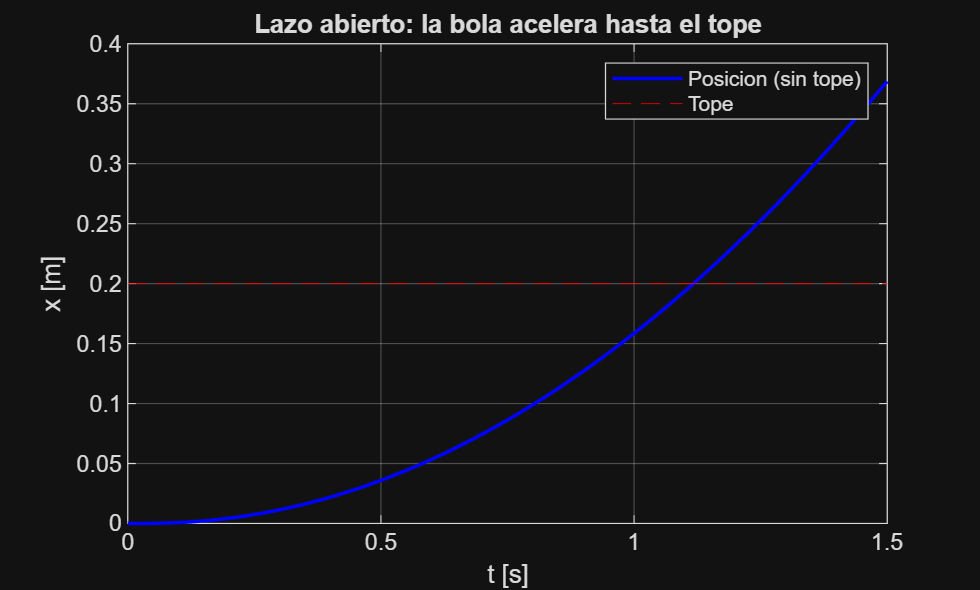

Kb = 5*9.81/7;
tau_servo = 0.05;
Gbb = tf(Kb, [1 0 0]) * tf(1, [tau_servo 1]);

theta0 = 0.05;                           % escalon de angulo: 0.05 rad (2.9 grados)
t = (0:0.02:1.5)';                       % Ts = 20 ms
x = theta0*step(Gbb, t);                 % posicion sin topes
x_tope = 0.20;                           % recorrido hasta el tope [m]

figure;
plot(t, x, 'b', 'LineWidth', 1.5); hold on; grid on;
yline(x_tope, '--r');
title('Lazo abierto: la bola acelera hasta el tope');
xlabel('t [s]'); ylabel('x [m]'); legend('Posicion (sin tope)', 'Tope');

## 8. Dos caminos para obtener Kb

**Camino 1: lazo abierto, ajuste de la parabola.** 

`Mientras la bola no llegue al tope, la posicion es aproximadamente:`

                                                                                                                 
$$x = \frac{1}{2} K_b \theta_0 (t - \tau)^2$$


`Tomando raiz cuadrada, la raiz de x resulta una recta en t: `

                                                                                                                
$$\sqrt{x} = \sqrt{\frac{K_b \theta_0}{2}} (t - \tau)$$


`Si m es la pendiente de esa recta, se despeja Kb:`

                                                                                                                 
$$K_b = \frac{2 m^2}{\theta_0}$$


`La ventaja de ajustar la raiz es que el retardo del servo solo desplaza la recta y no sesga la pendiente.`

idx = find(x >= x_tope, 1);
if isempty(idx), idx = numel(t); end
tt = t(1:idx);
xx = x(1:idx) + 0.0005*randn(idx, 1);    % ruido del sensor: 0.5 mm
sel = xx > 0.01;                         % descarto el arranque
p = polyfit(tt(sel), sqrt(xx(sel)), 1);
Kb_parabola = 2*p(1)^2/theta0;
fprintf('Camino 1 (parabola): Kb = %.2f   (real %.2f)\n', Kb_parabola, Kb);

Camino 1 (parabola): Kb = 6.90   (real 7.01)


**Camino 2: lazo cerrado con PD y el metodo de overshoot.**

`Se cierra el lazo con un controlador PD estable. Si la derivada se aplica sobre la medicion (no sobre el error), la ley de control es:`

                                                                 
$$u = K_p (r - x) - K_d \frac{dx}{dt}$$


`Con la planta ideal, el lazo cerrado queda exactamente de segundo orden, sin ceros:`

                                                            
$$T(s) = \frac{K_b K_p}{s^2 + K_b K_d s + K_b K_p}$$


`Comparando con la forma estandar de un segundo orden se obtiene:`

                                                                      
$$\omega_n^2 = K_b K_p$$


                                                                  
$$2 \zeta \omega_n = K_b K_d$$


`La ganancia en lazo cerrado es 1 (no aporta informacion). Los datos de la planta estan en zeta y wn. Despejando Kb:`

                                                                     
$$K_b = \frac{\omega_n^2}{K_p}$$


`Y como verificacion, la otra ecuacion da el mismo valor:`

                                                                   
$$K_b = \frac{2 \zeta \omega_n}{K_d}$$


Kp_t = 1.0;  Kd_t = 0.35;
T_cl = tf(Kb*Kp_t, [1, Kb*Kd_t, Kb*Kp_t]);

r_amp = 0.05;                            % escalon de referencia: 5 cm
tc = (0:0.02:8)';
xc = r_amp*step(T_cl, tc) + 0.0005*randn(size(tc));

[~, icl] = identificarEscalon(tc, xc, r_amp, 5);
Kb_cl1 = icl.wn^2/Kp_t;
Kb_cl2 = 2*icl.zeta*icl.wn/Kd_t;
fprintf('Camino 2 (lazo cerrado): Kb = %.2f (via wn^2/Kp), %.2f (via 2*zeta*wn/Kd)\n', ...
        Kb_cl1, Kb_cl2);

Camino 2 (lazo cerrado): Kb = 7.37 (via wn^2/Kp), 7.07 (via 2*zeta*wn/Kd)


fprintf('K en lazo cerrado = %.3f (deberia ser ~1)\n', icl.K);

K en lazo cerrado = 0.996 (deberia ser ~1)



% Ahora con la planta que incluye el polo del servo (el caso realista).
% El modelo de segundo orden ya no es exacto y aparece un error:
T_cl3 = Kp_t*feedback(Gbb, tf([Kd_t Kp_t], 1));
xc3 = r_amp*step(T_cl3, tc) + 0.0005*randn(size(tc));
[~, icl3] = identificarEscalon(tc, xc3, r_amp, 5);
fprintf('Con servo: Kb = %.2f (via wn^2/Kp)  -> error por modelo incompleto\n', icl3.wn^2/Kp_t);

Con servo: Kb = 6.84 (via wn^2/Kp)  -> error por modelo incompleto


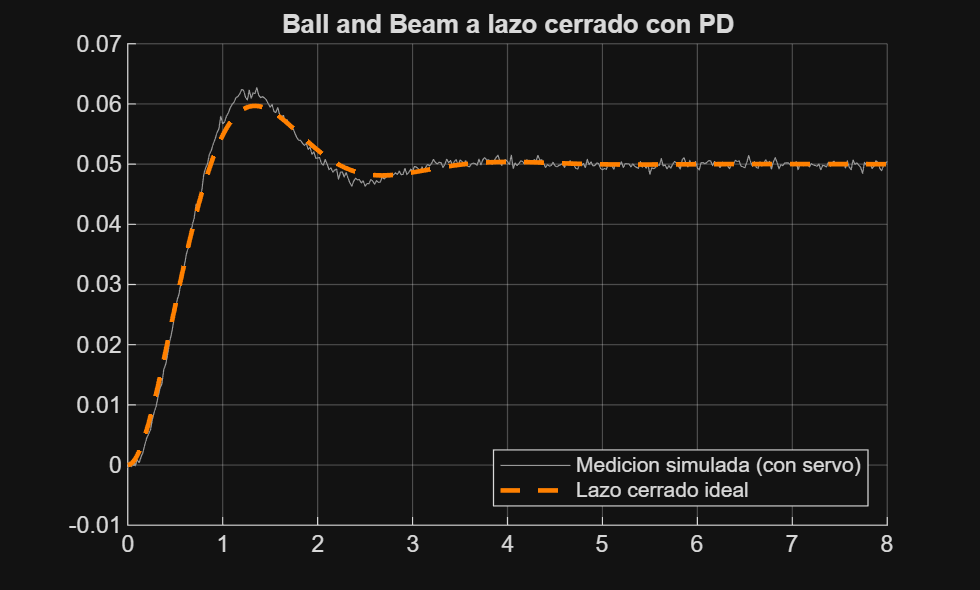


figure; hold on; grid on;
plot(tc, xc3, 'Color', [0.6 0.6 0.6], 'DisplayName', 'Medicion simulada (con servo)');
plot(tc, r_amp*step(T_cl, tc), '--', 'Color', [1.0 0.5 0.0], 'LineWidth', 2, ...
     'DisplayName', 'Lazo cerrado ideal');
legend('Location', 'southeast');
title('Ball and Beam a lazo cerrado con PD');

% *Nota practica:* el codigo PID_Compute del trabajo calcula la derivada
% sobre el *error*. Para este ensayo hay que aplicarla sobre la medicion
% (cambiando una linea) o aceptar que aparece un cero en T(s) y el metodo
% queda sesgado.

## 9. Del modelo al PID

*Hasta acá tenemos un número, Kb. Ahora armamos el modelo completo de la planta y probamos un PID sobre él, todo en simulación (sin tocar la maqueta).*

Los tres bloques del lazo

    *• Planta Gp: *lo que reacciona al controlador. Entrada: ángulo de la viga [rad]. Salida: posición de la bola [m]. Es el producto de dos partes: Kb sobre s al cuadrado (la bola, el doble integrador) y 1 sobre (tau s + 1) (el servo, que tarda un poco en alcanzar el ángulo pedido; tau = 0.05 s).

    *• Controlador C: *el PID en forma estándar, con Kp, Ti y Td. Se le agrega Tf, un filtro chico sobre la derivada (Tf = Td/10), para que no amplifique el ruido del sensor.

    *• Lazo abierto L: *es C seguido de Gp, sin realimentar. Sirve para analizar márgenes de estabilidad.

    *• Lazo cerrado T: *es el sistema completo con realimentación. Es lo que va a funcionar de verdad en la maqueta: entra la posición pedida y sale la posición de la bola.

La relación entre ellos es:

                                               
$$T(s) = \frac{L(s)}{1 + L(s)}$$


Entonces aca se define Gp, C, L y T, y después muestra el mismo sistema desde tres ángulos. Cada uno responde una pregunta distinta:

-  Sección 9a, respuesta al escalón: **¿cómo se mueve la bola cuando le pido ir a otra posición?**

-  Sección 9b, diagrama de Bode y márgenes: **¿cuánto margen tengo antes de que el sistema se vuelva inestable?**

-  Sección 9c, lugar de raíces: **¿dónde están los polos del sistema y cómo se moverían si cambio la ganancia?**

Unidades: Kp está en radianes por metro. Un error de 5 cm con Kp = 1 pide una inclinación de 0.05 rad (unos 2.9 grados).

Kb_id = Kb_parabola;                     % o Kb_cl1, o el promedio de varios ensayos
Gp = tf(Kb_id, [1 0 0]) * tf(1, [tau_servo 1]);   % planta: bola (Kb/s^2) por servo

% Constructor del PID en forma estandar con filtro en la derivada
pid_std = @(Kp, Ti, Td, Tf) Kp*(1 + tf(1, [Ti 0]) + tf([Td 0], [Tf 1]));

% Una sintonia automatica de MATLAB, solo como punto de partida de referencia.
% Ojo: la muestra en forma paralela (Kp, Ki, Kd), donde Ki = Kp/Ti y Kd = Kp*Td.
C0 = pidtune(Gp, 'PIDF');
disp(C0);

  pid with properties:

              Kp: 0.7006
              Ki: 0.0494
              Kd: 1.6708
              Tf: 8.5283e-04
        IFormula: ''
        DFormula: ''
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Nuestro PID propuesto
Kp = 1.0;  Ti = 10;  Td = 0.6;  Tf = Td/10;
C = pid_std(Kp, Ti, Td, Tf);
L = C*Gp;                                % lazo abierto
T = feedback(L, 1);                      % lazo cerrado

### 9a. Gráfico 1: respuesta al escalón del lazo cerrado

Aca deberíamos ver cómo se mueve la bola cuando le pido que vaya a otra posición. El eje horizontal es el tiempo. El eje vertical es la posición de la bola como proporción de la posición pedida: el valor 1 significa que la bola llegó exactamente adonde se le pidió.

Como el sistema es lineal, la forma de la curva no cambia con el tamaño del escalón. Un escalón de 5 cm da la misma curva multiplicada por 0.05. La tabla que imprime stepinfo resume la curva en números:

-  RiseTime: tiempo de subida, de 10 % a 90 % del valor final.

-  SettlingTime: tiempo hasta quedar dentro del 2 % del valor final.

-  Overshoot: sobrepico, en porcentaje.

-  PeakTime: instante en que ocurre el pico.

Con estos valores (Kp = 1, Ti = 10, Td = 0.6) y Kb cercano a 7, esperar algo cerca de: sobrepico 35 %, pico a 0.6 s, subida 0.2 s y asentamiento 1.6 s.

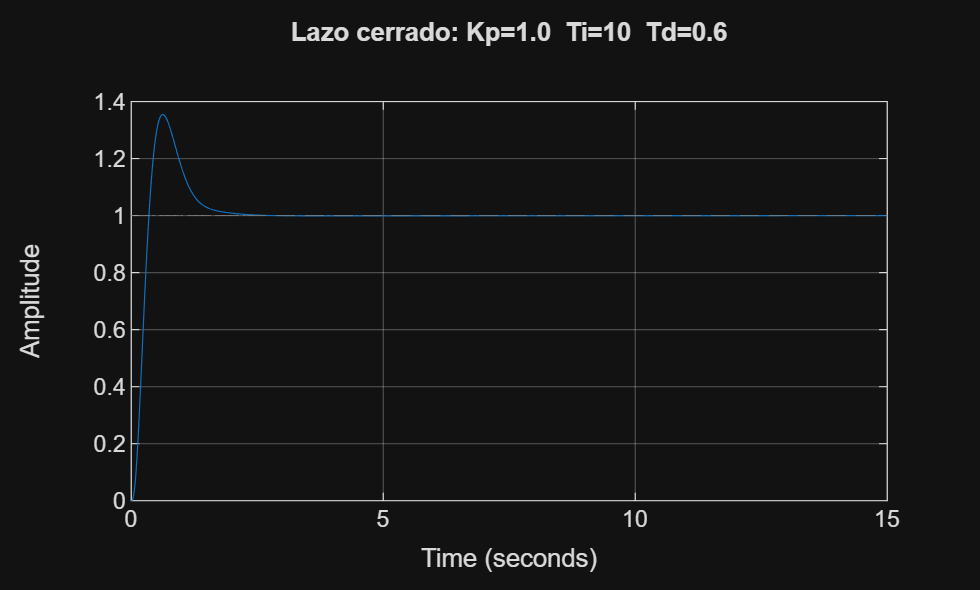

figure; step(T, 15); grid on;
yline(1, '--', 'Color', [0.5 0.5 0.5]);
title(sprintf('Lazo cerrado: Kp=%.1f  Ti=%.0f  Td=%.1f', Kp, Ti, Td));

disp(stepinfo(T));

         RiseTime: 0.2236
    TransientTime: 1.6271
     SettlingTime: 1.6271
      SettlingMin: 0.9055
      SettlingMax: 1.3547
        Overshoot: 35.4746
       Undershoot: 0
             Peak: 1.3547
         PeakTime: 0.6207



### 9b. Gráfico 2: diagrama de Bode y márgenes de estabilidad

Qué muestra: la respuesta en frecuencia del lazo abierto L. Son dos gráficos apilados, con la frecuencia en rad/s en el eje horizontal:

-  Arriba: la ganancia de L en decibelios. Donde cruza 0 dB (frecuencia de cruce) el lazo tiene ganancia 1.

-  Abajo: la fase de L en grados.

Cómo leerlo: en la frecuencia de cruce se mira cuánto le falta a la fase para llegar a -180 grados. Ese valor es el margen de fase (Pm), y el título del gráfico lo muestra. En general:

-  Pm de 40 a 60 grados: respuesta bien amortiguada.

-  Pm menor a 30 grados: muy oscilatorio.

-  Pm negativo: inestable.

Para este PID, el cruce está cerca de 4.6 rad/s y el margen de fase cerca de 43 grados.

Margen de ganancia (Gm): este sistema tiene un doble integrador más la acción integral, y por eso es inestable si se baja demasiado la ganancia. MATLAB puede mostrar entonces un margen de ganancia menor a 1 (negativo en decibelios). No es un error: para este caso el dato que importa es el margen de fase.

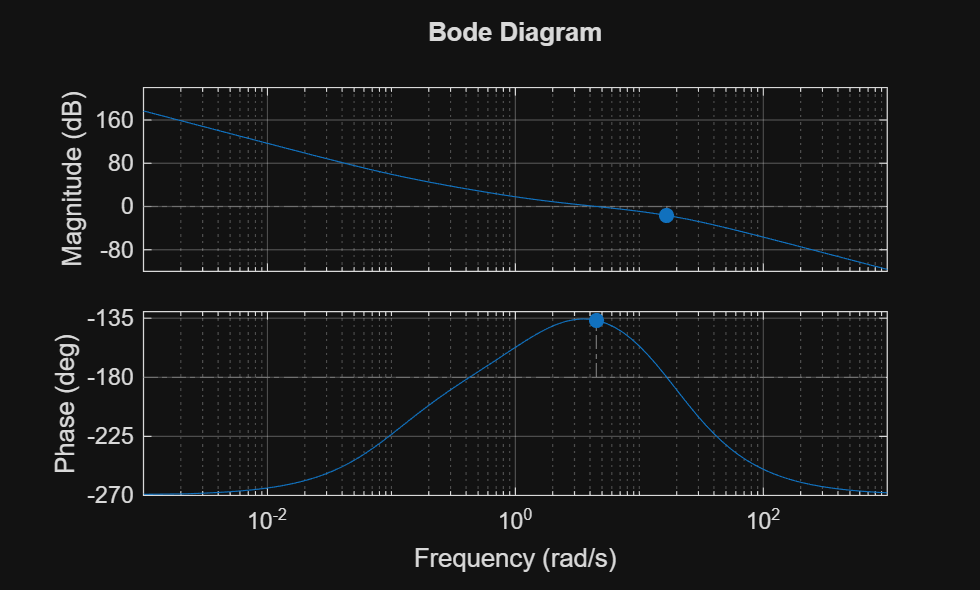

figure; margin(L); grid on;

### 9c. Gráfico 3: lugar de raíces y polos del lazo cerrado

Qué muestra: el plano complejo. El eje horizontal es la parte real y el vertical la parte imaginaria. Cada curva es el camino que recorre un polo del lazo cerrado cuando se multiplica la ganancia del lazo por un factor k que va de 0 a infinito.

-  Las X son los polos de L (donde empiezan las curvas, con k = 0).

-  Las O son los ceros de L (hacia donde terminan algunas curvas).

-  Las X rojas que agregamos son los polos actuales del lazo cerrado (k = 1).

-  Parte real negativa (a la izquierda del eje vertical): estable.

-  Parte real positiva: inestable. Si una curva cruza ese eje, hay una ganancia a partir de la cual el sistema se vuelve inestable.

Los polos que imprime la consola (esperar valores cercanos a estos):

-  Un par complejo cerca de -4.1 ± 4.3j: es el dominante. Determina el sobrepico y la velocidad de la respuesta (equivale a zeta cerca de 0.69 y wn cerca de 5.9).

-  Un polo real cerca de -2.4.

-  Un polo muy rápido cerca de -26: viene del filtro de la derivada y del servo. Casi no influye.

-  Un polo muy lento cerca de -0.1: viene de la acción integral. Es el que produce la cola lenta al final de la respuesta.

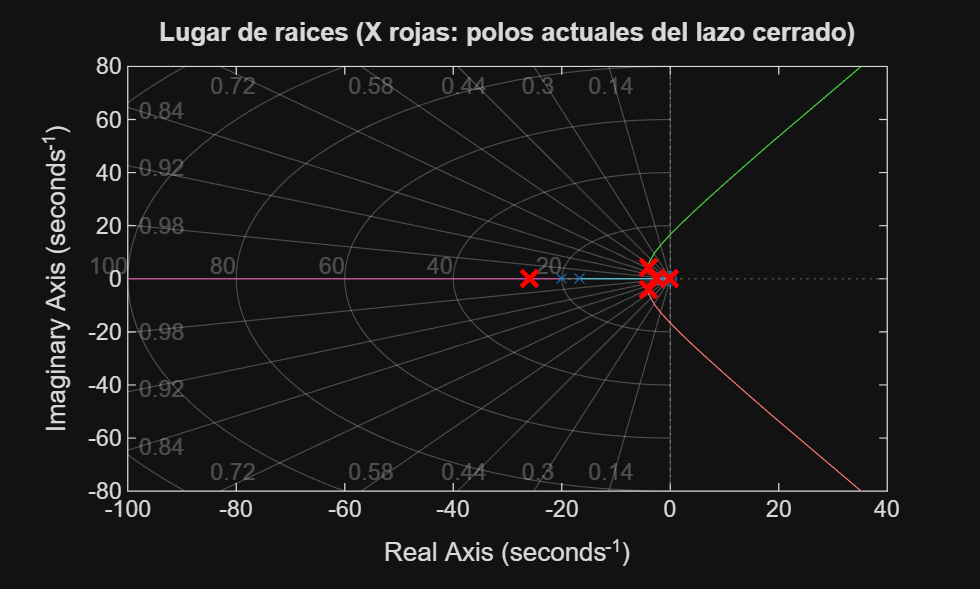

figure; rlocus(L); grid on; hold on;
polos = pole(T);
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
title('Lugar de raices (X rojas: polos actuales del lazo cerrado)');

disp('Polos del lazo cerrado:'); disp(polos);

Polos del lazo cerrado:
 -25.9387 + 0.0000i
  -4.0864 + 4.1499i
  -4.0864 - 4.1499i
  -2.4485 + 0.0000i
  -0.1067 + 0.0000i



Resumen de qué mirar en los tres gráficos:

- ** Todos los polos con parte real negativa = estable.**

- ** Margen de fase de 40 a 60 grados = amortiguamiento razonable.**

- ** El sobrepico de unos 35 % es mayor que el que daría solo el par dominante. El motivo es el cero que introduce la derivada aplicada sobre el error.**

- ** Ese sobrepico se reduce aplicando la derivada sobre la medición o con ponderación de setpoint. En el barrido de la sección 10 se ve cómo cambia con Kp, Ti y Td.**

## 10. Efecto de cada parametro (barridos)

Variamos un parametro a la vez y dejamos los otros fijos:

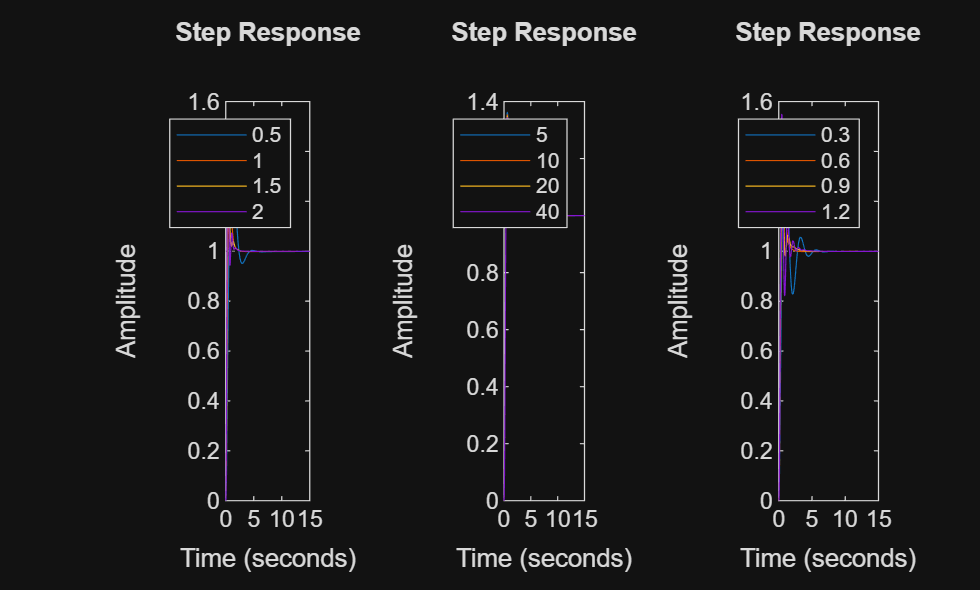

figure;
subplot(1,3,1); hold on; grid on; title('Barrido de Kp');
for kp = [0.5 1 1.5 2]
    step(feedback(pid_std(kp, Ti, Td, Tf)*Gp, 1), 15);
end
legend('0.5', '1', '1.5', '2');

subplot(1,3,2); hold on; grid on; title('Barrido de Ti');
for ti = [5 10 20 40]
    step(feedback(pid_std(Kp, ti, Td, Tf)*Gp, 1), 15);
end
legend('5', '10', '20', '40');

subplot(1,3,3); hold on; grid on; title('Barrido de Td');
for td = [0.3 0.6 0.9 1.2]
    step(feedback(pid_std(Kp, Ti, td, td/10)*Gp, 1), 15);
end
legend('0.3', '0.6', '0.9', '1.2');

## 11. Para que sirve la accion integral en el Ball and Beam

La planta ya tiene doble integrador, asi que un PD alcanza para seguir un escalon sin error. La integral se necesita por otra razon: una **perturbacion constante a la entrada** (por ejemplo, viga mal calibrada con un offset de angulo $d$).

Con un PD, en regimen la planta no acelera, asi que $u = -d$, es decir $K_p\,e = -d$ y queda un error $e = -d/K_p$. La integral lo corrige.

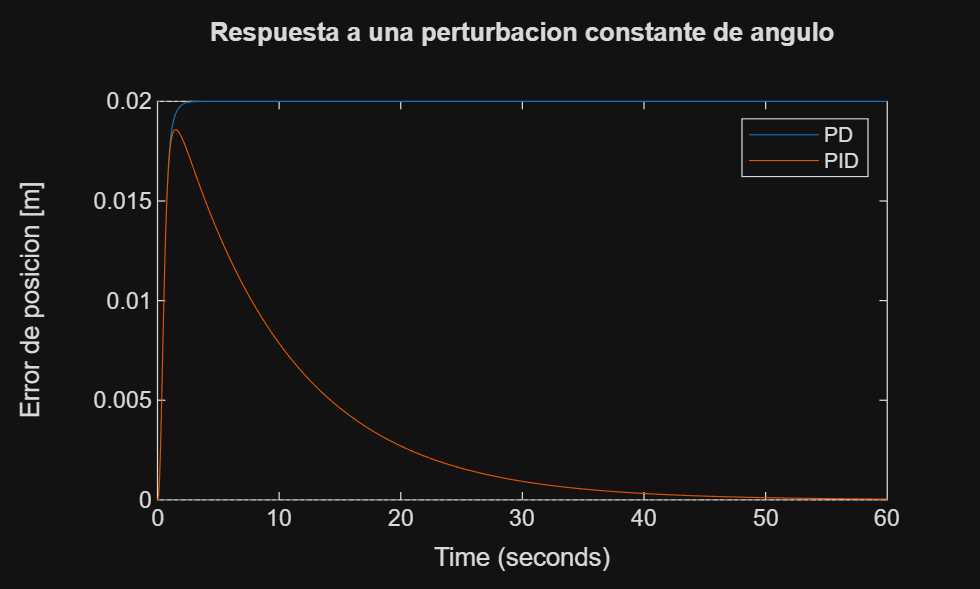

d = 0.02;                                % offset de angulo: 0.02 rad
C_pd = Kp*(1 + tf([Td 0], [Tf 1]));
figure; hold on; grid on;
step(d*feedback(Gp, C_pd), 60);          % PD: queda error permanente
step(d*feedback(Gp, C), 60);             % PID: el error vuelve a cero
legend('PD', 'PID');
title('Respuesta a una perturbacion constante de angulo');
ylabel('Error de posicion [m]');

## 12. Ziegler-Nichols y por que conviene tener un modelo

El metodo de Ziegler-Nichols a lazo cerrado del trabajo busca la ganancia $K_u$ que hace oscilar al sistema con solo accion P, y de ahi $K_p = 0.6K_u$, $T_i = 0.5T_u$, $T_d = 0.125T_u$.

Aplicado al modelo de la maqueta aparece un problema: con control P puro sobre un doble integrador mas el polo del servo, el lugar de raices pasa al semiplano derecho para **cualquier** ganancia positiva. No hay ganancia critica bien definida en el modelo. En la maqueta real el rozamiento agrega algo de amortiguamiento y la oscilacion se puede observar, pero depende de la friccion y es dificil de repetir.

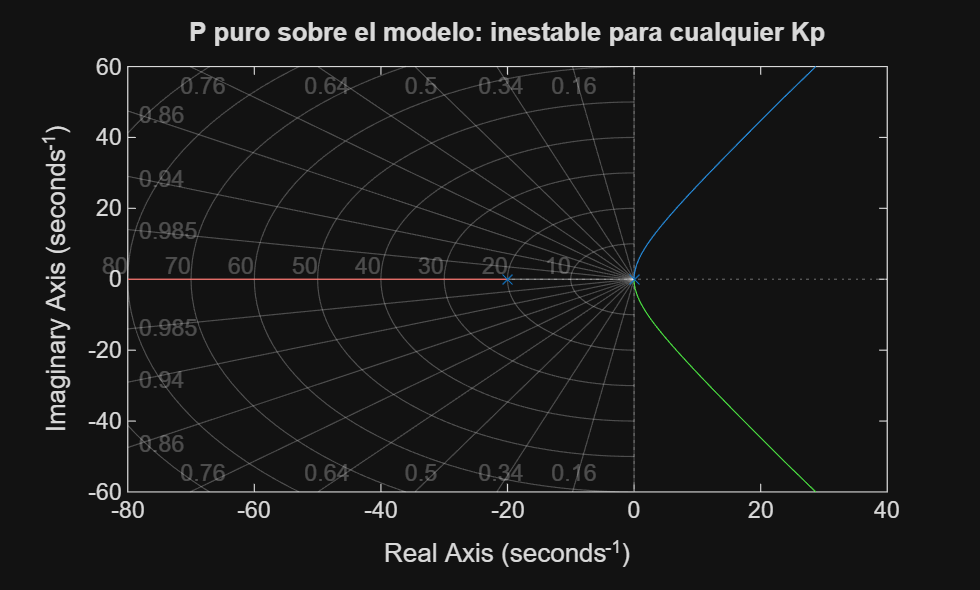

figure; rlocus(Gp); grid on;
title('P puro sobre el modelo: inestable para cualquier Kp');

% Con el modelo se puede disenar directamente por ubicacion de polos o por
% margenes y despues contrastar contra Ziegler-Nichols en la maqueta. Esa
% comparacion queda bien en un informe.

## 13. Discretizacion para el STM32

El microcontrolador ejecuta el PID cada $T_s$. Criterio del trabajo: $T_s$ entre 10 y 30 veces mas rapido que la dinamica dominante, y en la practica 20 a 50 ms por el servo (50 Hz) y el sensor.

Discretizamos el controlador con la transformacion bilineal (Tustin) y la planta con retenedor de orden cero (lo que hace el DAC o el PWM):

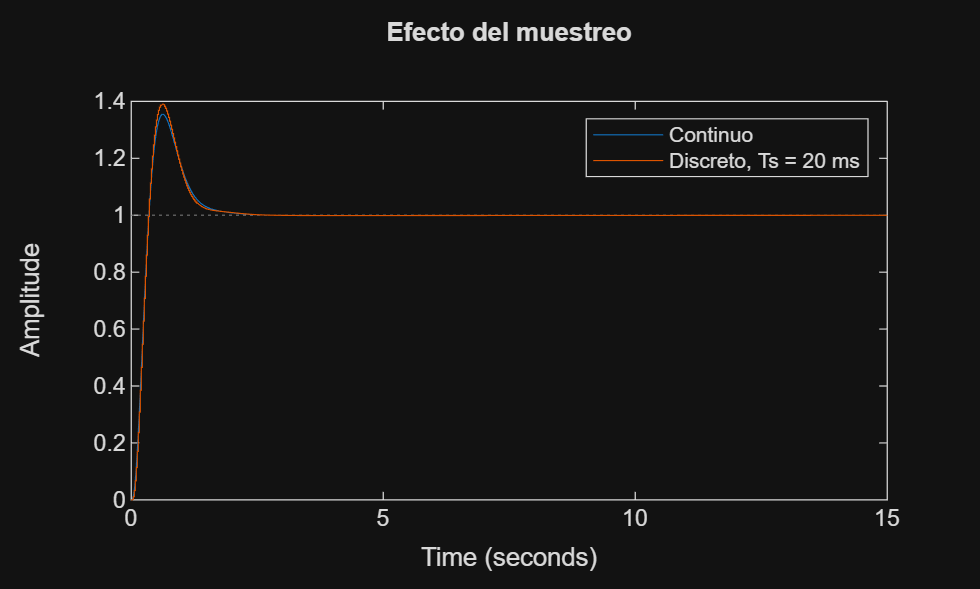

Ts = 0.02;
Cd = c2d(C, Ts, 'tustin');
Gd = c2d(Gp, Ts, 'zoh');
Td_cl = feedback(Cd*Gd, 1);

figure; hold on; grid on;
step(T, 15);
step(Td_cl, 15);
legend('Continuo', 'Discreto, Ts = 20 ms');
title('Efecto del muestreo');

Si ambas curvas casi coinciden, Ts es suficientemente chico. Probar Ts = 0.1 s para ver cuando el muestreo degrada el lazo.

## 14. Checklist para la maqueta

- Elegir el camino de identificacion (parabola a lazo abierto, o lazo cerrado con PD).

- Loguear a Ts = 20 ms, con $t=0$ en el escalon y $y(1)$ en reposo.

- Repetir 5 a 10 veces, en ambos sentidos, y promediar $K_b$.

- Filtrar con ventana corta (5 a 10 muestras) y verificar que el pico no se aplaste.

- Identificar parametros con la funcion identificarEscalon.

- Validar: superponer modelo y medicion.

- Disenar el PID en simulacion (secciones 9 a 11) y discretizar (seccion 13).

- Cargar en el STM32 y ajustar fino sobre la maqueta.

Para usar datos reales, reemplazar la medicion simulada por:

## Funcion auxiliar: identificarEscalon

Identifica un modelo de segundo orden subamortiguado a partir de la respuesta al escalon (valor final, sobrepico y tiempo de pico).

function [G, info] = identificarEscalon(t, y, A, nfilt)
    if nargin < 4, nfilt = 1; end
    t = t(:);  y = y(:);

    % t=0 es el instante del escalon e y(1) es la salida en reposo
    y = y - y(1);

    if nfilt > 1
        y = movmean(y, nfilt);           % media movil centrada
    end

    % Valor final: promedio del ultimo 10 % de la medicion
    n10 = max(5, round(0.10*numel(y)));
    yss = mean(y(end-n10+1:end));
    K   = yss/A;

    % Pico, sobrepico y tiempo de pico
    [ymax, idx] = max(y);
    Tp = t(idx);
    OS = (ymax - yss)/yss;
    if OS <= 0.001
        error('No hay sobrepico detectable: el metodo no aplica.');
    end

    % Parametros del segundo orden
    lnOS = log(OS);
    zeta = -lnOS/sqrt(pi^2 + lnOS^2);
    wn   = (pi/Tp)/sqrt(1 - zeta^2);

    G = tf(K*wn^2, [1, 2*zeta*wn, wn^2]);
    info = struct('K', K, 'zeta', zeta, 'wn', wn, 'OS', OS, 'Tp', Tp, ...
                  'yss', yss, 'ymax', ymax);
end